# Pneumonia Detection from Chest X-ray Images

#### Authors: Emma Ziegenbein, Patrick Kennedy, Annie Nguyen, Anastasia Izraztsov

#### Course: BME3053C Computer Applications for BME

#### Term: Spring 2022

#### J. Crayton Pruitt Family Department of Biomedical Engineering

#### University of Florida

#### April 24, 2022

clc; clear; close all;

### Create Data Stores

d1 = "Dataset/stage_2_test_images/Test_Positive/";
Pfiles = dir(fullfile(d1));
Pfiles([Pfiles.isdir]) = [];
n_Pfiles = length(Pfiles);

d2 = "Dataset/stage_2_test_images/Test_Negative/";
Nfiles = dir(fullfile(d2));
Nfiles([Nfiles.isdir]) = [];
n_Nfiles = length(Nfiles);

### Create Labels

pos_label = strings(n_Pfiles,1);
pos_label(1:end) = "positive";
neg_label = strings(n_Nfiles,1);
neg_label(1:end) = "negative";
labels = [pos_label;neg_label];


### Initiate Variables

LungSize = zeros(size(labels));
AveValues = zeros(size(labels));

### Image Processing (Positive Training Images)

for i = 1:n_Pfiles
     filename = fullfile(d1, Pfiles(i).name);

#### Read Image File, Convert to Grayscale, and Adjust Intensity Values

    img = dicomread(filename);
    img = im2gray(img);
    img = imadjust(img);

#### Invert Image, Clear Image Border, and Uninvert Image

    testimg = imcomplement(img); 
    testimg_clear = imclearborder(testimg);
    testimg_clear_inv = imcomplement(testimg_clear); 

#### Detect the Lungs

    I = testimg_clear_inv;
    [BW, thresh] = edge(I,'sobel');
    fudgeFactor = 0.8;
    Iedge = edge(I,'sobel',fudgeFactor*thresh);

#### Dilate the Image, Fill Interior Holes in the Image, and Erode the Image

    se90 = strel('line',6,90);
    se0 = strel('line',3,0);
    Idilate = imdilate(Iedge,[se90, se0]);
    Ifill = imfill(Idilate, 'holes');
    seD = strel('diamond', 3);
    Ierode = imerode(Ifill,seD); % 1st erosion
    Ierode = imerode(Ierode,seD); % 2nd erosion
    Ierode = imerode(Ierode,seD); % 3rd erosion
    Ifinal = imerode(Ierode,seD); % Final (4th) erosion

#### Calculate Variable Values

    Ave_val = mean(img(Ifinal));
    num_pixels = sum(Ifinal(:));

#### Add Calculated Variable Values to Variable Arrays

    LungSize(i) = num_pixels;
    AveValues(i) = Ave_val;
end

### Image Processing (Negative Training Images)

for j = 1:n_Nfiles
     filename = fullfile(d2, Nfiles(j).name);

#### Read Image File, Convert to Grayscale, and Adjust Intensity Values

    img = dicomread(filename);
    img = im2gray(img);
    img = imadjust(img);

#### Invert Image, Clear Image Border, and Uninvert Image

    testimg = imcomplement(img); 
    testimg_clear = imclearborder(testimg);
    testimg_clear_inv = imcomplement(testimg_clear); 

#### Detect the Lungs

    I = testimg_clear_inv;
    [BW, thresh] = edge(I,'sobel');
    fudgeFactor = 0.8;
    Iedge = edge(I,'sobel',fudgeFactor*thresh);

#### Dilate the Image, Fill Interior Holes in the Image, and Erode the Image

    se90 = strel('line',6,90);
    se0 = strel('line',3,0);
    Idilate = imdilate(Iedge,[se90, se0]);
    Ifill = imfill(Idilate, 'holes');
    seD = strel('diamond', 3);
    Ierode = imerode(Ifill,seD); % 1st erosion
    Ierode = imerode(Ierode,seD); % 2nd erosion
    Ierode = imerode(Ierode,seD); % 3rd erosion
    Ifinal = imerode(Ierode,seD); % Final (4th) erosion

#### Calculate Variable Values

    Ave_val = mean(img(Ifinal));
    num_pixels = sum(Ifinal(:));

#### Add Calculated Variable Values to Variable Arrays

    LungSize(n_Pfiles+j) = num_pixels;
    AveValues(n_Pfiles+j) = Ave_val;
end   

### Load models

addpath('Trained_Models\')
load KNN;
load LDA;
load Tree;

### Test Models

KNN_predict = KNN.predict([LungSize,AveValues]);
LDA_predict = LDA.predict([LungSize,AveValues]);
Tree_predict = Tree.predict([LungSize,AveValues]);

### Evaluate Models Using Confusion Matrices

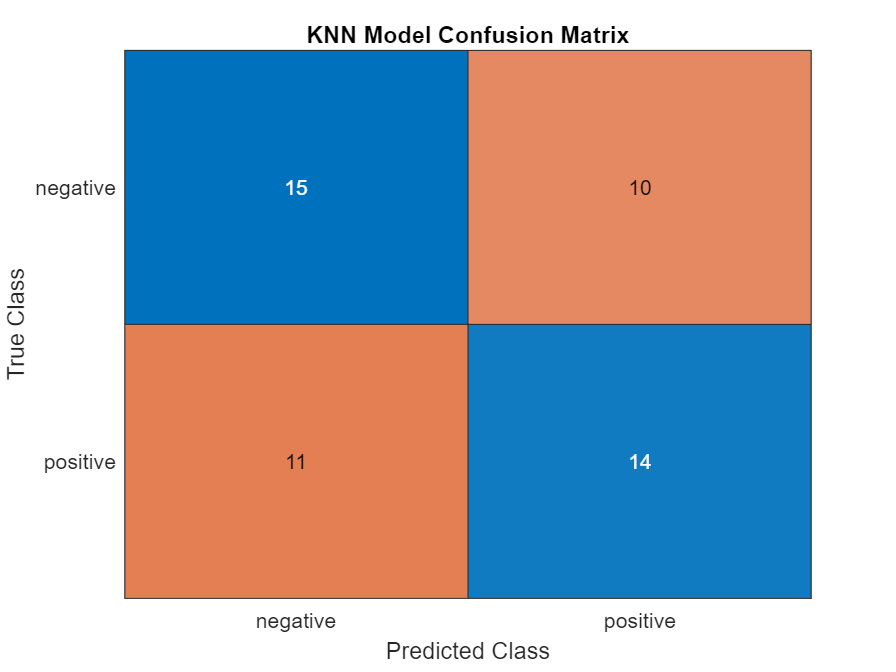

figure(4)
cell_labels = cellstr(labels);
confusionchart(cell_labels,KNN_predict)
title("KNN Model Confusion Matrix");

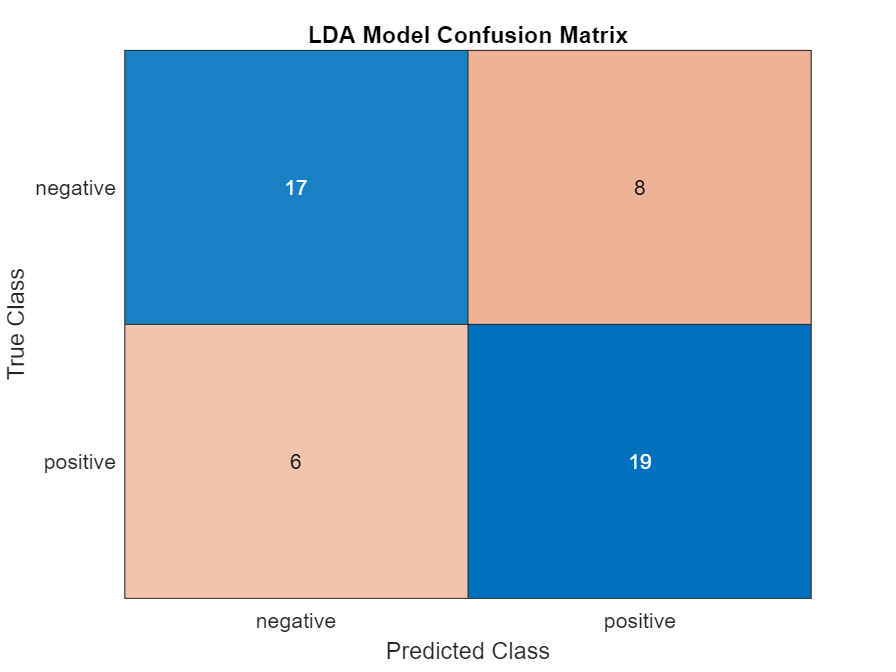


figure(5)
confusionchart(cell_labels,LDA_predict)
title("LDA Model Confusion Matrix");

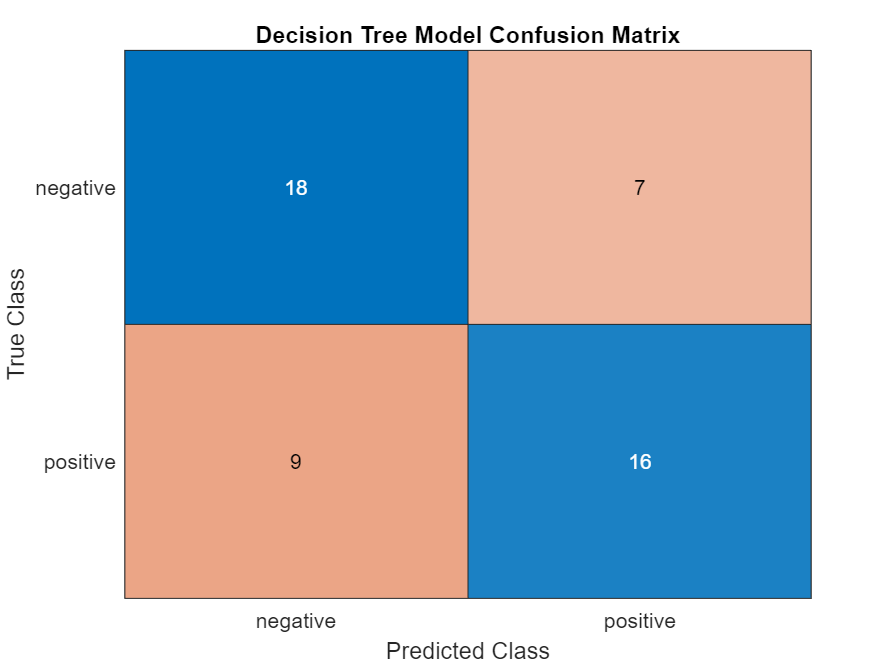


figure(6)
confusionchart(cell_labels,Tree_predict)
title("Decision Tree Model Confusion Matrix");